% 功能：
%   文件名称: ch2_fig25.m
%   matlab绘图模板 | 2D绘图模板1
% 核心变量：
%   name: comment
% 备注：
%

## 初始化环境?

close all;
clear;
clc;

## 设置图片保存信息 %%

设置图片保存文件夹路径

figSaveFold = "C:/F/课程/数字信号处理教材编撰/2021/模板/ch2";
% 设置图片保存名
figSaveName = "ch2_fig25.svg";
% 图片保存完整路径
figSavePath = sprintf("%s/%s",figSaveFold,figSaveName);
% 设置图片显示的名称?
figName = "ch2_fig25";

## 设置数据 %%

## 设置纵轴 | 一般是实际数据(因变量)

纵轴数据

yData = [1,1,1,1,1,1,1,1,1,1,1,1,1,1,1];
% 纵轴单位
%yLabel = "幅度";
% 纵轴刻度 | 数字矢量
yTick = 0:0.2:1.2;
% 纵轴刻度文本 | cell数组,里面是char数组
yTickLabel = {'0','0.2','0.4','0.6','0.8','1.0',' '};

Attribute_Set = {'LineWidth',1.5};        % 箭头属性及其取值，设置箭头宽度为1.5

## 设置横轴 | 一般是自变量(自变量)

横轴数据

xData =[0,0.1,0.2,0.3,0.4,0.5,0.6,0.7,0.8,0.9,1,1.1,1.2,1.3,1.4];
% 横轴单位
%xLabel = "T";
% 横轴刻度
xTick = 0.2:0.2:1.4;
% 横轴刻度文本
xTickLabel = {'0.2','0.4','0.6','0.8','1.0','1.2','1.4'};

## 绘图 %%

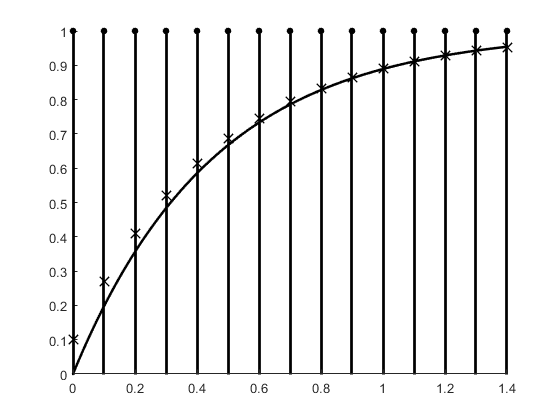

% 创建一个fig对象
fig = figure("Name",figName);
% 统黑线、上箭头、线宽为1
stem(xData,yData,'filled','Color','k','Marker','.','markersize',15,'LineWidth',2);
hold on
yData1 = 0.1;
for i=0:1:27
    yData1 = 0.1+0.9*yData1;
    yData_1(i+1) = yData1;
end
yData_11(1) = 0.1;
for i = 1:1:14
    yData_11(i+1) = yData_1(2*i);
end
x1 = scatter(xData,yData_11,100,'k');
set(x1,'Marker','x','LineWidth',1);
xData_2 = 0:0.001:1.4;
yData_2 = 1-exp(-2.2*xData_2);
plot(xData_2,yData_2,'Color','k','Marker','.','LineWidth',0.5);
%scatter();
% 设置纵轴
%ylabel(yLabel,'FontSize',12,'FontWeight','bold','Color','k')
% 设置横轴
%xlabel(xLabel,'FontSize',12,'FontWeight','bold','Color','k')
box off

## 配置图片 %%

## 设置纵轴

设置yLabel 设置yTick

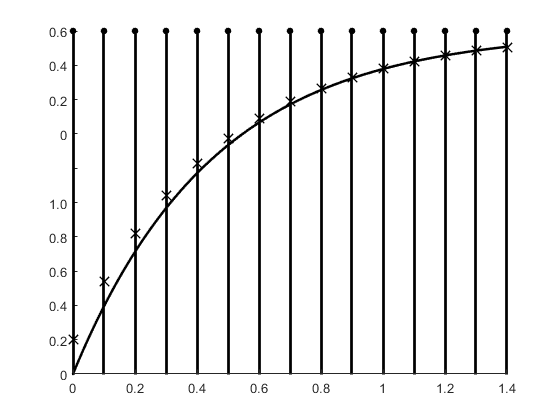

%set(gca,'YTick',yTick);
% 设置yTickLabel
set(gca,'YTickLabel',yTickLabel);
% 设置y轴在0处?
set(gca,'YAxisLocation','origin')

## 设置横轴

设置xLabel 设置xTick

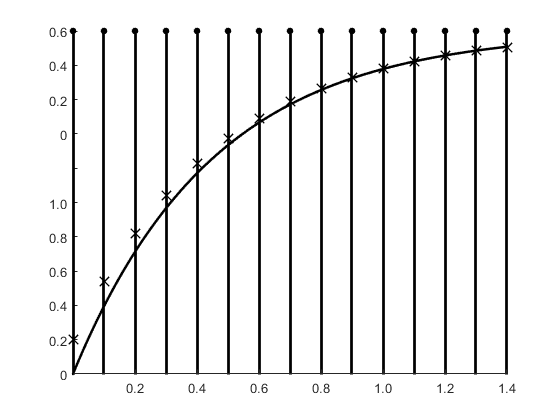

set(gca,'XTick',xTick);
% 设置xTickLabel
set(gca,'XTickLabel',xTickLabel);
% 设置x轴在0处?
set(gca,'XAxisLocation','origin')

## 设置整体图片

设置图片的大小 | 宽为400像素,高位3000像素,图片左下角坐标(100,100)

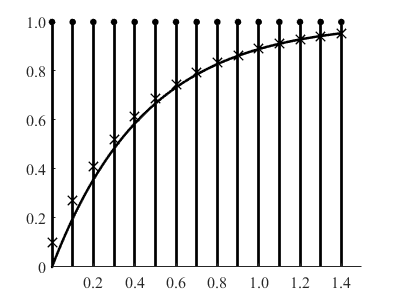

set(fig,'Units','pixels','Position',[100 100 400 300]);
% 先把汉字设置为宋体?
set(gca,'FontName','宋体')
% 设置字体为Times New Roman
set(gca,'FontName','Times New Roman','FontSize',12);

## 保存 %%

saveas(fig,figSavePath,'svg');